# F-16A Level 2 Sizing Analysis — Class-Based Example

This live script performs a Fidelity Level 2 sizing pass for the F-16A example using the toolkit classes supplied with the project. This version captures the W_TO value returned by SizingClassLevel2.size_aircraft().

Main objects used: * AircraftDesign * GeometryLevel2 * AeroLevel2 * PropulsionLevel2 * WeightLevel2 * MissionAnalysisLevel2 * ConstraintAnalysisClass * Requirements * SizingClassLevel2

The script assumes the corresponding class files, import utilities, design workbook, requirements table, constraints table, and mission profile are on the MATLAB path.

clear; close all;

## Project setup

Set this to the folder containing your classes, import utilities, design spreadsheet/workbook, requirements file, constraints file, and mission data.

projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";

## Create the aircraft design object

AircraftDesign is the project-level object. It imports the design geometry, fuselage data, propulsion data, weight data, general aircraft data, and requirements reference.

design = AircraftDesign( ...
    designName, ...
    RequirementsName = requirementsName, ...
    ConstraintsName  = constraintsName, ...
    AutoLoad         = true);

## Build the Level 2 analysis objects

Level 2 uses more design geometry than Level 1. GeometryLevel2 computes component wetted areas from exposed planform/body estimates, AeroLevel2 uses equivalent skin-friction and wetted-area buildup for CD0, PropulsionLevel2 estimates installed TSFC from Mach/altitude/engine type, and WeightLevel2 uses a more parameterized empty-weight regression.

geometry_obj     = F16GeometryLevel2(design);
aero_obj         = F16AeroLevel2(geometry_obj);
propulsion_obj   = F16PropulsionLevel2();
weight_obj       = F16WeightLevel2(design, geometry_obj);
mission_obj      = F16MissionAnalysisLevel2(missionName);
constraint_obj   = ConstraintAnalysisClass(design);

requirements_obj = Requirements(design);
sizing_obj       = F16SizingLevel2();

aero_obj.Cf = aero_obj.get_Cf(0.0035); % Initializing Cf manually because it's tabulated.

## Initialize constraints

We require constraints like "optimum wing-loading" and "minimum T/W" for sizing computations. So we'll initialize them, here.

constraint_obj.constraint_analysis % Requires zero arguments since it pulls from the constraint table.

% constraint_obj.show_constraints %% Optional; remove at leisure

## Run the project sizing class

This calls your SizingClassLevel3 method directly and captures the returned takeoff gross weight. The sizing class still displays its internal iteration table. A persistent trace is reconstructed in the next section for plots and reporting.

results_table = sizing_obj.size_aircraft( ...
    design, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj, ...
    propulsion_obj, ...
    constraint_obj, ...
    requirements_obj, ...
    aero_obj);


## Synchronize object properties used by the plots

% Keep the sizing table available through both the returned variable and the sizing object.
if istable(results_table)
    sizing_obj.results_table = results_table;
else
    results_table = sizing_obj.results_table;
end

assert(istable(results_table) && height(results_table) > 0, ...
    "F16SizingLevel2.size_aircraft must return/populate a non-empty results_table.");

% Synchronize the existing objects to the final sizing-row values before plotting.
finalSizingRow = results_table(end, :);
weight_obj.W_TO = finalSizingRow.WTO_new;
weight_obj.W_fixed = finalSizingRow.W_fixed;
weight_obj.OEW = finalSizingRow.Empty_weight;
weight_obj.OEW_frac = finalSizingRow.Empty_weight_fraction;
weight_obj.total_fuel_used = finalSizingRow.WTO_new - finalSizingRow.W_fixed - finalSizingRow.Empty_weight;
weight_obj.fuel_fraction = finalSizingRow.Fuel_fraction;

geometry_obj.mainwings.S_ref = finalSizingRow.S_ref_w;
geometry_obj.design.S_wet = finalSizingRow.S_wet_design;

propulsion_obj.T0 = constraint_obj.min_TW * weight_obj.W_TO;

% Store per-segment fuel burn in the existing mission object property.
mission_obj.mission_fuel = buildLevel2MissionFuelTable( ...
    mission_obj, ...
    propulsion_obj, ...
    design, ...
    geometry_obj, ...
    constraint_obj, ...
    weight_obj, ...
    aero_obj);

% Match the total fuel property to the plotted segment table.
weight_obj.total_fuel_used = sum(mission_obj.mission_fuel.FuelUsed_lbf, "omitnan");
weight_obj.fuel_fraction = weight_obj.total_fuel_used * 1.06 / weight_obj.W_TO;

% Build aerodynamic coefficient data for every flight-capable mission segment.
aeroMissionCoefficients = buildLevel2AeroCoefficientTable( ...
    aero_obj, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj);

% Keep declared AeroLevel2 scalar properties synchronized to cruise when available.
cruiseIdx = find(aeroMissionCoefficients.Segment == "Cruise", 1);
if isempty(cruiseIdx)
    cruiseIdx = 1;
end
if ~isempty(cruiseIdx) && height(aeroMissionCoefficients) >= cruiseIdx
    aero_obj.CD0 = aeroMissionCoefficients.CD0(cruiseIdx);
    aero_obj.K   = aeroMissionCoefficients.K(cruiseIdx);
end

% Build final component/mission weight table for plotting and saving.
componentWeightBreakdown = buildLevel2ComponentWeightBreakdown(weight_obj);


## Plot gross-weight convergence

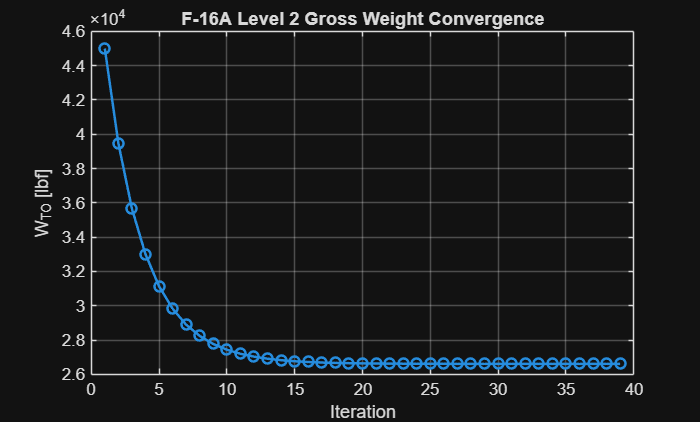

figure('Name', 'Level 2 Gross Weight Convergence');
iterationIdx = 1:height(results_table);
plot(iterationIdx, results_table.WTO, '-o', 'LineWidth', 1.5); grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 2 Gross Weight Convergence');

## Plot closure error

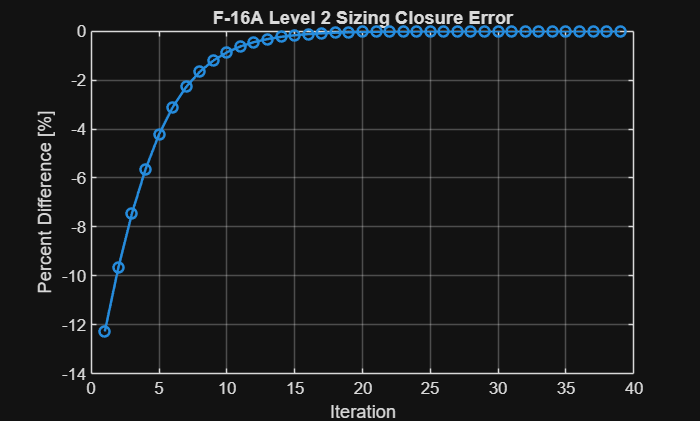

figure('Name', 'Level 2 Closure Error');
iterationIdx = 1:height(results_table);
plot(iterationIdx, results_table.Percent_Diff, '-o', 'LineWidth', 1.5); grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 2 Sizing Closure Error');

## Plot component weight breakdown

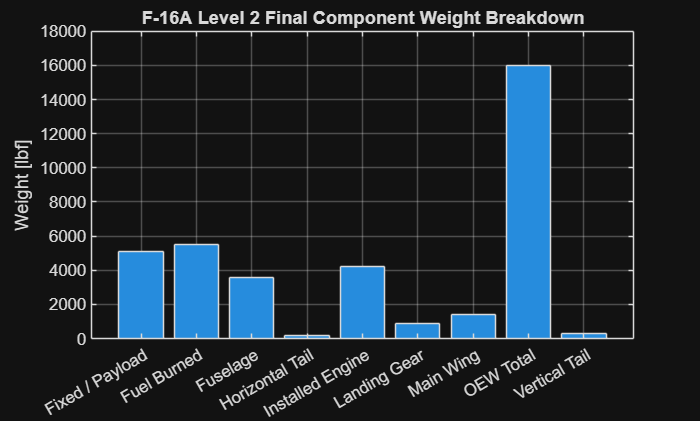

figure('Name', 'Level 2 Final Component Weight Breakdown');
bar(categorical(componentWeightBreakdown.Component), componentWeightBreakdown.Weight_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 2 Final Component Weight Breakdown');

## Plot fuel burned at each mission segment

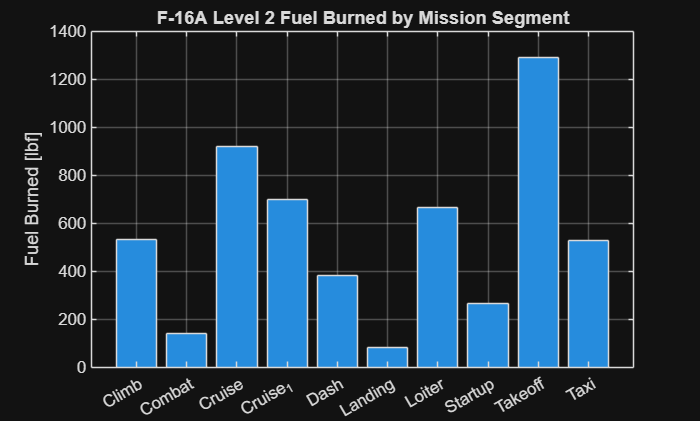

figure('Name', 'Level 2 Fuel Burned by Mission Segment');
bar(categorical(mission_obj.mission_fuel.Segment), mission_obj.mission_fuel.FuelUsed_lbf);
grid on;
ylabel('Fuel Burned [lbf]');
title('F-16A Level 2 Fuel Burned by Mission Segment');

## Plot aerodynamic coefficients at each mission segment

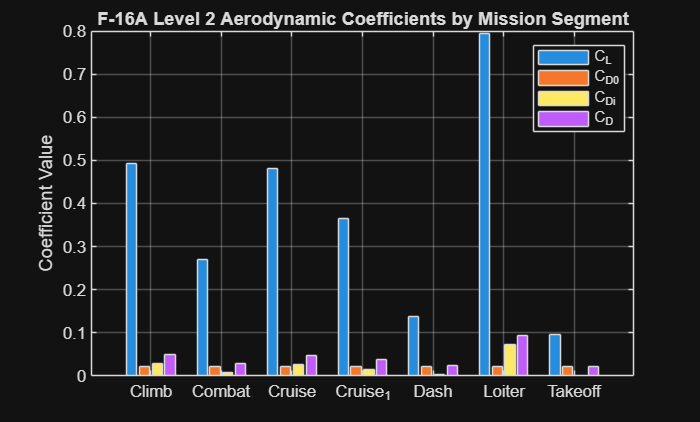

figure('Name', 'Level 2 Aerodynamic Coefficients by Mission Segment');
bar(categorical(aeroMissionCoefficients.Segment), ...
    [aeroMissionCoefficients.CL, ...
     aeroMissionCoefficients.CD0, ...
     aeroMissionCoefficients.CDi, ...
     aeroMissionCoefficients.CD]);
grid on;
ylabel('Coefficient Value');
title('F-16A Level 2 Aerodynamic Coefficients by Mission Segment');
legend({'C_L', 'C_{D0}', 'C_{Di}', 'C_D'}, 'Location', 'best');

## Save results into the AircraftDesign object

AircraftDesign is a handle class, so these assignments persist on the design object during this MATLAB session.

design.WeightResults.Level2SizingTable = results_table;
design.WeightResults.W_TO              = weight_obj.W_TO;
design.WeightResults.OEW               = weight_obj.OEW;
design.WeightResults.FuelUsed          = weight_obj.total_fuel_used;
design.WeightResults.FixedWeight       = weight_obj.W_fixed;
design.WeightResults.Level2MissionFuel = mission_obj.mission_fuel;
design.WeightResults.Level2ComponentWeights = componentWeightBreakdown;

design.AeroResults.Level2.Cf = aero_obj.Cf;
design.AeroResults.Level2.e_osw = aero_obj.e_osw;
design.AeroResults.Level2.CD0 = aero_obj.CD0;
design.AeroResults.Level2.K = aero_obj.K;
design.AeroResults.Level2.MissionCoefficients = aeroMissionCoefficients;

design.PropulsionResults.Level2.T0 = propulsion_obj.T0;

fprintf("\nSaved Level 2 sizing/plot data back into design.WeightResults, design.AeroResults, and design.PropulsionResults.\n");


Saved Level 2 sizing/plot data back into design.WeightResults, design.AeroResults, and design.PropulsionResults.


## Local helper functions

function value = getFieldOrNaN(s, fieldName)
    value = NaN;

    if isstruct(s) && isfield(s, fieldName)
        value = s.(fieldName);
    elseif istable(s) && any(strcmp(s.Properties.VariableNames, fieldName))
        value = s.(fieldName);
    end

    if iscell(value) && numel(value) == 1
        value = value{1};
    end

    if ~(isscalar(value) && isnumeric(value) && isfinite(value))
        value = NaN;
    end
end

function txt = getFieldText(s, fieldName, defaultText)
    txt = string(defaultText);

    if isstruct(s) && isfield(s, fieldName)
        raw = s.(fieldName);
    elseif istable(s) && any(strcmp(s.Properties.VariableNames, fieldName))
        raw = s.(fieldName);
    else
        return
    end

    if iscell(raw)
        raw = raw{1};
    end

    raw = string(raw);
    raw = replace(raw, '"', '');
    raw = strtrim(raw);

    if strlength(raw) > 0 && ~ismissing(raw)
        txt = raw;
    end
end

function normalizedName = normalizeSegmentName(rawName)
    normalizedName = erase(string(rawName), '_');
    normalizedName = erase(normalizedName, {'0','1','2','3','4','5','6','7','8','9'});
end

function missionFuel = buildLevel2MissionFuelTable(mission_obj, propulsion_obj, design, geometry_obj, constraint_obj, weight_obj, aero_obj)
    segmentNames = fieldnames(mission_obj.missiondata);

    W_TO = weight_obj.W_TO;
    W_S = constraint_obj.optimal_WS;
    S_ref = geometry_obj.mainwings.S_ref;
    S_wet_aircraft = geometry_obj.design.S_wet;
    AR = geometry_obj.mainwings.AR;
    T0 = propulsion_obj.T0;
    engine_type = design.propulsion_type;

    W_segments = nan(1, numel(segmentNames));
    fuelBurned = nan(1, numel(segmentNames));
    W_segments(1) = W_TO;

    segment = strings(0,1);
    W_in = nan(0,1);
    W_out = nan(0,1);
    fuel = nan(0,1);
    powerSetting = strings(0,1);
    TSFC_1_per_s = nan(0,1);

    for i = 1:numel(segmentNames)
        rawName = string(segmentNames{i});
        currentsegment = normalizeSegmentName(rawName);

        if currentsegment == "meta"
            break
        end

        segData = mission_obj.missiondata.(segmentNames{i});
        M = getFieldOrNaN(segData, 'MachNumber');
        alt = getFieldOrNaN(segData, 'Altitudeft');
        q = getFieldOrNaN(segData, 'qlbfft2');
        a = getFieldOrNaN(segData, 'afts');
        CD0 = aero_obj.get_design_CD0(aero_obj.Cf, S_wet_aircraft, S_ref);

        dryOrWet = getFieldText(segData, 'DryOrWet', 'Dry');
        if strcmpi(dryOrWet, "Wet")
            pwr = "max";
        else
            pwr = "mil";
        end

        if isfinite(M) && isfinite(alt)
            TSFC = propulsion_obj.get_TSFC_installed(engine_type, [M, alt], pwr);
        else
            TSFC = NaN;
        end

        if currentsegment == "Startup"
            win = W_segments(i);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_startup(W_segments(i));
        elseif currentsegment == "Taxi"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_taxi(W_segments(i-1));
        elseif currentsegment == "Takeoff"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_takeoff(W_segments(i-1));
        elseif currentsegment == "Climb"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_climb(W_TO, W_segments(i-1), M, S_ref, CD0, mission_obj.missiondata.Cruise.e, AR, TSFC, alt, T0);
        elseif currentsegment == "Cruise"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_cruise(W_segments(i-1), W_S, TSFC, mission_obj.missiondata.Cruise.Rangeft, M, a, q, CD0, mission_obj.missiondata.Cruise.e, AR, W_TO, S_ref);
        elseif currentsegment == "Dash"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_dash(W_segments(i-1), W_S, W_TO, q, CD0, mission_obj.missiondata.Dash.e, AR, TSFC, mission_obj.missiondata.Dash.Rangeft, M * a);
        elseif currentsegment == "Combat"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_combat(W_segments(i-1), mission_obj.missiondata.Combat.Timemin, TSFC, mission_obj.missiondata.Combat.PayloadDroplbf, CD0, mission_obj.missiondata.Combat.e, AR, W_TO, q, W_S);
        elseif currentsegment == "Loiter"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_loiter(W_TO, W_segments(i-1), W_S, q, CD0, mission_obj.missiondata.Loiter.e, AR, mission_obj.missiondata.Loiter.Timemin, TSFC);
        elseif currentsegment == "Landing"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_landing(W_segments(i-1), W_TO);
        elseif currentsegment == "Descent"
            continue
        else
            error("Couldn't identify mission segment name: %s", rawName);
        end

        segment(end+1,1) = rawName;
        W_in(end+1,1) = win;
        W_out(end+1,1) = W_segments(i);
        fuel(end+1,1) = fuelBurned(i);
        powerSetting(end+1,1) = pwr;
        TSFC_1_per_s(end+1,1) = TSFC;
    end

    missionFuel = table(segment, W_in, W_out, fuel, powerSetting, TSFC_1_per_s, ...
        'VariableNames', {'Segment', 'W_in_lbf', 'W_out_lbf', 'FuelUsed_lbf', 'PowerSetting', 'TSFC_1_per_s'});
end

function aeroMission = buildLevel2AeroCoefficientTable(aero_obj, geometry_obj, mission_obj, weight_obj)
    segmentNames = fieldnames(mission_obj.missiondata);

    segment = strings(0,1);
    mach = nan(0,1);
    altitude = nan(0,1);
    W_in = nan(0,1);
    CL = nan(0,1);
    CD0 = nan(0,1);
    CDi = nan(0,1);
    CD = nan(0,1);
    K = nan(0,1);
    drag = nan(0,1);

    S_ref = geometry_obj.mainwings.S_ref;

    for i = 1:numel(segmentNames)
        rawName = string(segmentNames{i});
        segData = mission_obj.missiondata.(segmentNames{i});

        M = getFieldOrNaN(segData, 'MachNumber');
        h_ft = getFieldOrNaN(segData, 'Altitudeft');

        if ~isfinite(M) || ~isfinite(h_ft) || M <= 0
            continue
        end

        W_seg = getSegmentInputWeight(mission_obj.mission_fuel, rawName, weight_obj.W_TO);
        state_input = [M, h_ft, 0, W_seg];

        dragResults = aero_obj.get_design_drag(geometry_obj, state_input);
        q = getFieldOrNaN(segData, 'qlbfft2');
        if ~isfinite(q) || q <= 0
            q = AeroUtils.compute_q(state_input);
        end

        CL_seg = computeCLForPlot(W_seg, q, S_ref);
        CD0_seg = dragResults.CD0;
        CD_seg = dragResults.CD;
        K_seg = aero_obj.K;
        CDi_seg = max(CD_seg - CD0_seg, 0);

        segment(end+1,1) = rawName;
        mach(end+1,1) = M;
        altitude(end+1,1) = h_ft;
        W_in(end+1,1) = W_seg;
        CL(end+1,1) = CL_seg;
        CD0(end+1,1) = CD0_seg;
        CDi(end+1,1) = CDi_seg;
        CD(end+1,1) = CD_seg;
        K(end+1,1) = K_seg;
        drag(end+1,1) = dragResults.D;
    end

    aeroMission = table(segment, mach, altitude, W_in, CL, CD0, CDi, CD, K, drag, ...
        'VariableNames', {'Segment', 'Mach', 'Altitude_ft', 'W_in_lbf', 'CL', 'CD0', 'CDi', 'CD', 'K', 'Drag_lbf'});
end

function CL = computeCLForPlot(W, q, S_ref)
    try
        CL = AeroUtils.compute_CL(W, q, S_ref);
    catch
        CL = W / (q * S_ref);
    end
end

function W_seg = getSegmentInputWeight(missionFuel, segmentName, defaultWeight)
    W_seg = defaultWeight;

    if istable(missionFuel) && any(strcmp(missionFuel.Properties.VariableNames, 'Segment')) && any(strcmp(missionFuel.Properties.VariableNames, 'W_in_lbf'))
        names = string(missionFuel.Segment);
        idx = find(names == segmentName, 1);

        if isempty(idx)
            idx = find(normalizeSegmentName(names) == normalizeSegmentName(segmentName), 1);
        end

        if ~isempty(idx) && isfinite(missionFuel.W_in_lbf(idx))
            W_seg = missionFuel.W_in_lbf(idx);
        end
    end
end

function componentWeightBreakdown = buildLevel2ComponentWeightBreakdown(weight_obj)
    component = [ ...
        "Main Wing"; ...
        "Horizontal Tail"; ...
        "Vertical Tail"; ...
        "Fuselage"; ...
        "Landing Gear"; ...
        "Installed Engine"; ...
        "Fuel Burned"; ...
        "Fixed / Payload"; ...
        "OEW Total"];

    weight_lbf = [ ...
        safeScalar(weight_obj.wings); ...
        safeScalar(weight_obj.HT); ...
        safeScalar(weight_obj.VT); ...
        safeScalar(weight_obj.fuselage); ...
        safeScalar(weight_obj.landinggear); ...
        safeScalar(weight_obj.engine); ...
        safeScalar(weight_obj.total_fuel_used); ...
        safeScalar(weight_obj.W_fixed); ...
        safeScalar(weight_obj.OEW)];

    componentWeightBreakdown = table(component, weight_lbf, ...
        'VariableNames', {'Component', 'Weight_lbf'});
end

function value = safeScalar(value)
    if isempty(value) || ~isscalar(value) || ~isnumeric(value) || ~isfinite(value)
        value = NaN;
    end
end

